# Parallel Reactions in a PFR with Heat Effects

This example MATLAB Live Script is is adapted from Example 12-5 from Elements of Chemical Reaction Engineering 5th Edition by H. Scott Fogler. In this example we will model the behavior of parallel reactions in a nonisothermal PFR.

## Learning Objectives

- After completing this lesson, participants should be able to translate a system of ODEs into a MATLAB function.

- After completing this lesson, participants should be able to use **ode45** to solve a system of ODEs.

- After completing this lesson, participants should be able to create plots using MATLAB.

- After completing this lesson, participants should be able to model parallel reactions in a PFR with heat effects.

## Problem Statement

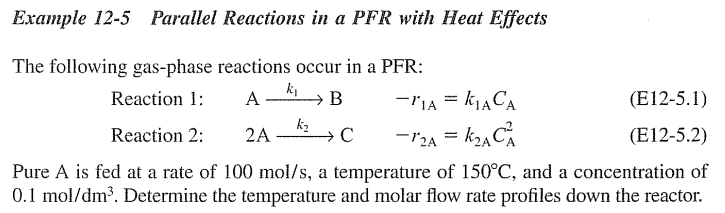

### Initial Values

Input the range of volume the ODEs will be evaluated across. This code could be condensed to "Vspan = 0:0.01:1;" but was written in long form to be more comprehensible to students unfamiliar with MATLAB.

clear all % clears all existing variables from memory
clc % clears the command window
Vmin = 0; 
Vmax = 1; % dm^3
Number_of_Steps = 101;
Vspan = linspace(Vmin,Vmax,Number_of_Steps); % dm^3

Input the initial molar flow rates and consolidate them into a vector.

T = 423; % deg_K
F_A = 100; % mol/s
F_B = 0; % mol/s
F_C = 0; % mol/s
F_and_T = [F_A, F_B, F_C, T]; % Consolidate initial conditions into a vector

## Solve ODEs

Solve the system of ODEs contained in the **ODEs** function below. Note that when writing this code the call for the ODE solver (the line that includes **ode45**) must go before the ODE function. In fact, the ODE function needs to be placed at the end of the code.

[Vspan, F_and_T]=ode45(@ODEs, Vspan, F_and_T);

**ode45** performs well with most ODE problems and should generally be your first choice of solver. See this webpage for more MATLAB ODE solvers and their uses: [https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

## Plot Solution

Plot the temperature and molar flow rate profiles down the reactor.

Note that we have different line styles and colors in the plots. The general plot formatting options are 

- Colors: black 'k', green 'g', red 'r', blue 'b', magenta 'm',  cyan blue 'c', yellow 'y'.

- Line types: '-' solid line, '--' dashed line, '-.' dash-dot line, ':' dotted line.

- Colors and line styles can be combined as 'r:' or 'k-.' for a red dotted line or a black dash-dot line.

- See this webpage for more details: [https://www.mathworks.com/help/matlab/ref/plot.html](https://www.mathworks.com/help/matlab/ref/plot.html) 

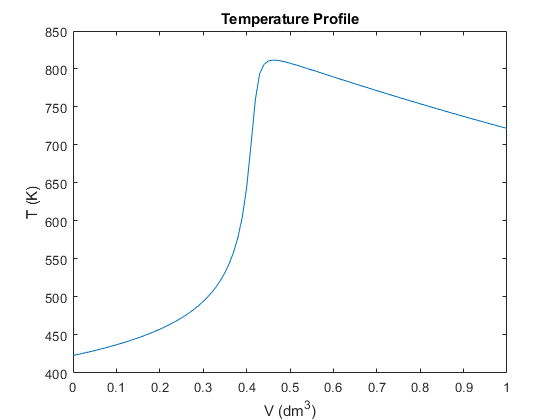

figure(1) % Plot T vs. V graph
    plot(Vspan, F_and_T(:,4))
    title('Temperature Profile')
    xlabel('V (dm^3)')
    ylabel('T (K)')

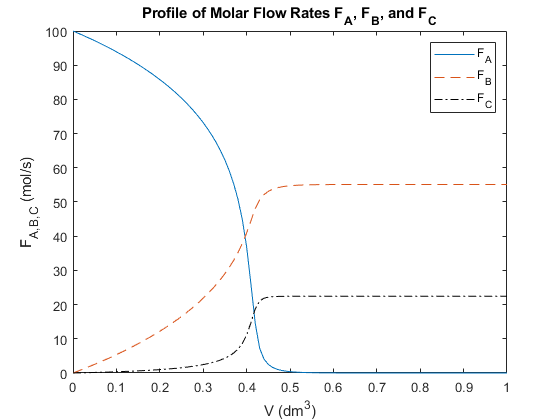


figure(2) %Plot (F_A, F_B, F_C) vs. V graph
    plot(Vspan, F_and_T(:,1), Vspan, F_and_T(:,2), '--', Vspan, F_and_T(:,3), 'k-.')
    title('Profile of Molar Flow Rates F_A, F_B, and F_C')
    xlabel('V (dm^3)')
    ylabel('F_A_,_B_,_C (mol/s)')
    legend('F_A', 'F_B', 'F_C')

Using the default parameter values, the plots should resemble the following Polymath plots:

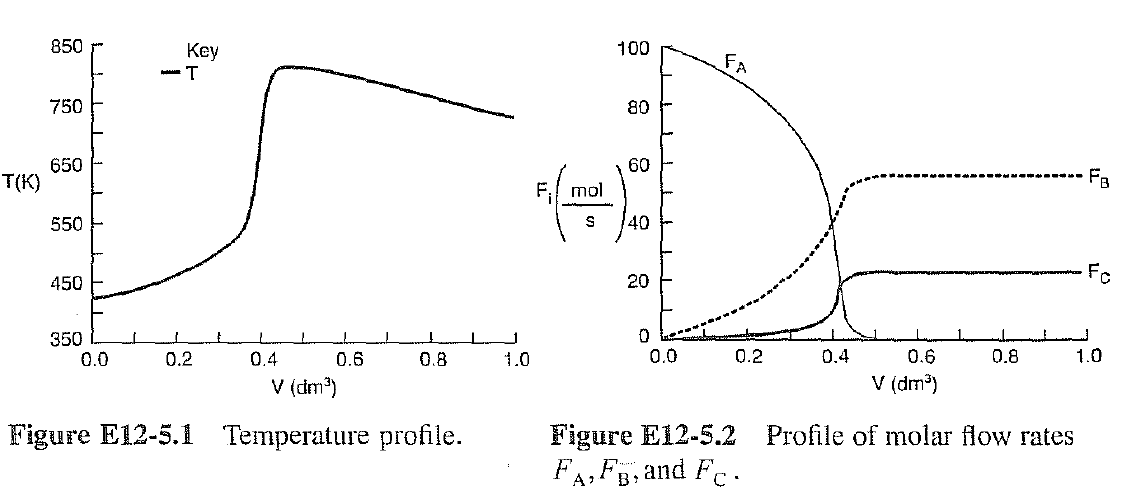

## ODEs Function

Define the system of ODEs within a MATLAB function. This will allow us to use ode45 to solve this system of ODEs. 

### Extract the molar flow rates and temperature from the vector we passed into the function, F_and_T.

function dF_dV = ODEs(Vspan, F_and_T)
F_A = F_and_T(1); % mol/s
F_B = F_and_T(2); % mol/s
F_C = F_and_T(3); % mol/s
T  = F_and_T(4); % deg_K

### Default parameters and additional information from the problem statement


$$\Delta H_{Rx1A} = 20,000 \;\text{J/(mol of A reacted in reaction 1)}$$



$$\Delta H_{Rx2A} = -60,000 \;\text{J/(mol of A reacted in reaction 2)}$$



$$C_{P_A} = 90 \; \text{J/mol}^{\circ}\text{C}$$



$$C_{P_B} = 90 \; \text{J/mol}^{\circ}\text{C}$$



$$C_{P_C} = 180 \; \text{J/mol}^{\circ}\text{C}$$



$$U_a = 4000 \; \text{J/m}^3\text{s}^{\circ}\text{C}$$



$$T_a = 100\;^{\circ}\text{C (Constant)}$$



$$\frac{E_1}{R} = 4000 \; \text{K}$$



$$\frac{E_2}{R} = 9000 \; \text{K}$$



$$C_{A_0} = C_{T_0} = 0.1\;\frac{\text{mol}}{\text{dm}^3}$$


C_T0 = 0.1; % Units unknown
T_0 = 423; % deg_K

% Additional information
delta_H_Rx1A = -20000; % J/(mol of A reacted in reaction 1)
delta_H_Rx2A = -60000; % J/(mol of B reacted in reaction 2)

C_P_A = 90; % J/mol*deg_C
C_P_B = 90; % J/mol*deg_C
C_P_C = 180; % J/mol*deg_C
U_a = 4000; % J/m^3*s*deg_C
T_a = 373; % deg_K (Constant)

E_1overR = 4000; %K
E_2overR = 9000; %K

### Explicit equations for the two rate constants


$$k_{1A} = 10\;\text{exp}[\frac{E_1}{R}(\frac{1}{300}-\frac{1}{T})]\text{s}^{-1}$$



$$k_{2A} = 0.09\;\text{exp}[\frac{E_2}{R}(\frac{1}{300}-\frac{1}{T})]\frac{\text{dm}^3}{\text{mol s}}$$


k_1A = 10*exp((E_1overR)*((1/300)-(1/T)));  % 1/s
k_2A = 0.09*exp((E_2overR)*((1/300)-(1/T))); % dm^3/mol*s

### Explicit equations related to the stoichiometry of the gas phase, $\Delta P=0$


$$F_T = F_A + F_B + F_C$$



$$C_A = C_{T_0}(\frac{F_A}{F_T})(\frac{T_0}{T})$$



$$C_B = C_{T_0}(\frac{F_B}{F_T})(\frac{T_0}{T})$$



$$C_C = C_{T_0}(\frac{F_C}{F_T})(\frac{T_0}{T})$$


F_T = F_A + F_B + F_C; % Total molar flow rate in mol/s
C_A = C_T0*(F_A/F_T)*(T_0/T);
C_B = C_T0*(F_B/F_T)*(T_0/T); % Not used
C_C = C_T0*(F_C/F_T)*(T_0/T); % Not used

### Rate laws


$$r_{1A}=-k_{1A}C_A$$



$$r_{2A}=-k_{2A}C_A^2$$


r_1A = -k_1A*C_A;
r_2A = -k_2A*(C_A^2);

### Relative rates for each reaction


$$\frac{r_{1A}}{-1} = \frac{r_{1B}}{1}; \quad r_{1B} = -r_{1A} = k_{1A}C_A$$



$$\frac{r_{2A}}{-2} = \frac{r_{2B}}{1}; \quad r_{2C} = -\frac{1}{2}r_{2A} = \frac{k_{2A}}{2}C_A^2$$


r_1B = -r_1A; % Reaction 1
r_2C = -0.5*r_2A; % Reaction 2

### Net rates for each species


$$r_A = r_{1A} + r_{2A} = -k_{1A}C_A-k_{2A}C_A^2$$



$$r_B = r_{1B} = k_{1A}C_A$$



$$r_C = r_{2C} = \frac{1}{2}k_{2A}C_A^2$$


r_A = r_1A + r_2A;
r_B = r_1B;
r_C = r_2C;

### Mole Balances


$$\frac{dF_A}{dV}=r_A$$



$$\frac{dF_B}{dV}=r_B$$



$$\frac{dF_C}{dV}=r_C$$


dF_A_dV = r_A;
dF_B_dV = r_B;
dF_C_dV = r_C;

### PFR Energy Balance


$$\frac{dT}{dV}=\frac{U_a(T_a-T)\;+\;(-r_{1A})(\Delta H_{Rx1A})\;+\;(-r_{2A})(\Delta H_{Rx2A})}{F_A C_{P_A}\;+\;F_B C_{P_B}\;+\;F_C C_{P_C}}$$


dT_dV = (((U_a*(T_a-T))+((-r_1A)*(-delta_H_Rx1A))+((-r_2A)*(-delta_H_Rx2A)))/((F_A*C_P_A)+(F_B*C_P_B)+(F_C*C_P_C)));

### Consolidate function output into a single vector and close the function

dF_dV = [dF_A_dV; dF_B_dV; dF_C_dV; dT_dV];
end

## Reflection Questions

- Why would two plots be helpful for this problem?

- Do the plots match the expected behavior of a PFR?

- Did you perform a dimensional analysis to ensure the given parameters' units and the solution's units match?